clc

clear all
load("C:\Users\BLooDek\Desktop\numerical-methods\series.mat");
%Task 10, ID 14 -> 15 x_star_10_1= [0.213882, 0.736311] x_star_10_2 = [6.334504,-18.810192]
ID = 15;
a11 = ((-1)^series(ID + 2))*series(ID);
a12 = ((-1)^series(ID + 3))*series(ID+1);
a21 = ((-1)^series(ID + 4))*series(ID+2);
a22 = ((-1)^series(ID + 5))*series(ID+3);
b1 = ((-1)^series(ID + 6))*series(ID+4);
b2 = ((-1)^series(ID + 7))*series(ID+5); 
a = [a11 a12; a21 a22]; b = [b1 b2]' 

b =      8
     6


z=-20:0.1:20;
f= @(x) [ a11*x(1)^2 + (a21*b1+b2)*x(1) + a12*x(2)-b1; a21*x(1)^2 + (a12*b2+b1)*x(1)+a22*x(2)-b2 ];
Df= @(x) [ 2*a11*x(1)+a21*b1+b2, a12; a21*2*x(1) + a12*b2+b1, a22];
fz = (-a11*z.^2-(a21*b1+b2)*z)/a12;
fz2=(-a21*z.^2-(a12*b2+b1)*z)/a22;
[x_star, iter] =  NumerMeth_tasks_09_10(f, Df, [-5 5], [0], 1000)

x_star =     0.2139    0.7363


iter = 6

x_start1 =  NumerMeth_tasks_09_10(f, Df, [5 20], [0], 1000)

x_start1 =     6.3345  -18.8102


f(x_star)

ans = 	1.0e+-14 *

    0.1776
         0


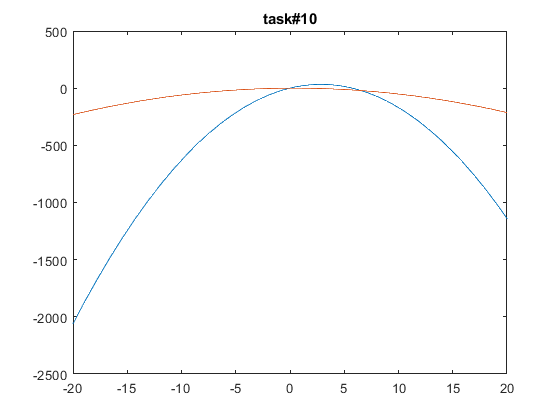

figure(2)
plot(z,fz)
hold on
plot(z,fz2)
title('task#10');